clear
clc
T = load('aerocoeffs_2.mat').full;
mach = T.mach;
mach_cut = mach(1:14,1);
AoA = T.AoA(14:end,1);
aoa_cut = AoA(14:end,1);
CL = T.CL;
CD = T.CD;
CN = T.CNa;

CN =     0.0789    0.0815    0.0839    0.0865    0.0896    0.0943    0.1190    0.1236    0.1105    0.1216    0.1337    0.1472    0.1725    0.1658    0.1203    0.1233
    0.0763    0.0782    0.0804    0.0825    0.0854    0.0896    0.1061    0.1124    0.1001    0.1100    0.1204    0.1270    0.1579    0.1624    0.1101    0.1108
    0.0733    0.0751    0.0768    0.0786    0.0811    0.0852    0.0999    0.1027    0.0892    0.0989    0.1079    0.1134    0.1352    0.1501    0.1093    0.1042
    0.0704    0.0717    0.0732    0.0745    0.0770    0.0806    0.0939    0.0962    0.0772    0.0885    0.0960    0.1006    0.1114    0.1333    0.1212    0.0961
    0.0674    0.0684    0.0695    0.0706    0.0728    0.0762    0.0879    0.0900    0.0701    0.0762    0.0850    0.0888    0.0975    0.1085    0.1114    0.0930
    0.0642    0.0650    0.0658    0.0667    0.0687    0.0718    0.0821    0.0839    0.0633    0.0673    0.0735    0.0778    0.0847    0.0910    0.1151    0.0822
    0.0610    0.0616    0.062

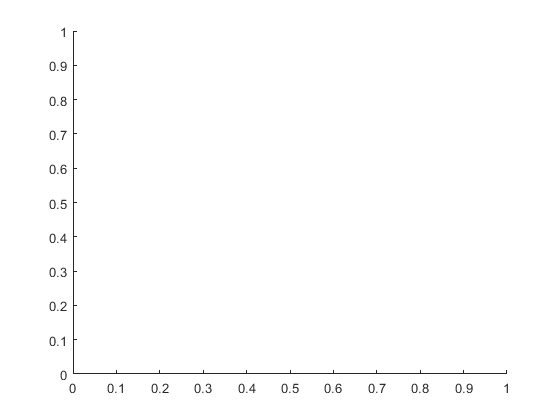

cl = cell(length(mach));
cd = cell(length(mach));
cn = cell(length(mach));
figure
i = 0;
for t = 1 : length(mach)
    i = i + 1;
    cl_fun{i} = polyfit(AoA,CL(14:end,t),3);
    % plot(AoA, polyval(a{i}, AoA));
    % hold on
end
hold off;

j = 0;
for t = 1 : length(mach)
    j = j + 1;
    cd_fun{j} = polyfit(AoA,CD(14:end,t),3);
    % plot(AoA, polyval(b{j}, AoA));
    % hold on
end

k = 0;
for t = 1 : length(mach)
    k = k + 1;
    cn_fun{k} = polyfit(AoA,CD(14:end,t),3);
%     plot(AoA, polyval(cd_fun{k}, AoA));
%     hold on
end


save(which('cl_fun.mat'),'cl_fun');
save(which('cd_fun.mat'),'cd_fun');
save(which('cn_fun.mat'),'cn_fun');

clc;
% Take the measured mach and compare with the mach-array from ESA.
% Take use the function that corresponds the absolute value is closest to 0.
mach_esa = mach;
%mach_esa = movmean(mach_esa,2);
%mach_esa = mach_esa(2:end);
mach_meas = mach;

dist    = abs(mach_esa - 0.13);
minDist = min(dist);
idx     = find(dist == minDist);





% n = 14;
% mach_mat = repmat(mach,1,n)'; %Mach matrix with each index value repeated 14 times
% mach_arr = reshape(mach_mat,1,[])';
% 
% m = 16;
% aoa_arr =repmat(AoA, m, 1); %Mach matrix with each index value repeated 14 times
% 
% CL_cut = CL(14:end,:); % AOA >= 0
% CL_arr =  reshape(CL_cut,1,[])'; % Making (14*16) x 1 array
% 
% 
% 
% 
% sf = fit([aoa_arr,mach_arr],CL_arr,'poly22','normalize','on')







